# Example B from Lecture L3b:  solving for splines

Let's "fake" some data first: 

close all; clear all; clc

We set up some control points (as row vectors): 

%    x  y
p = [1, 1; 
     2, 2; 
     3, 2; 
     3, 3]

p =      1     1
     2     2
     3     2
     3     3


%
% Alternatively: 
% p = [0, 0;  3, 0;  3, 2;  2, 2;  2, 3;  3, 3;  4, 4;  5, 3;  6, 2;  6, 1;  6, 0]
%

Let's have a look at them:

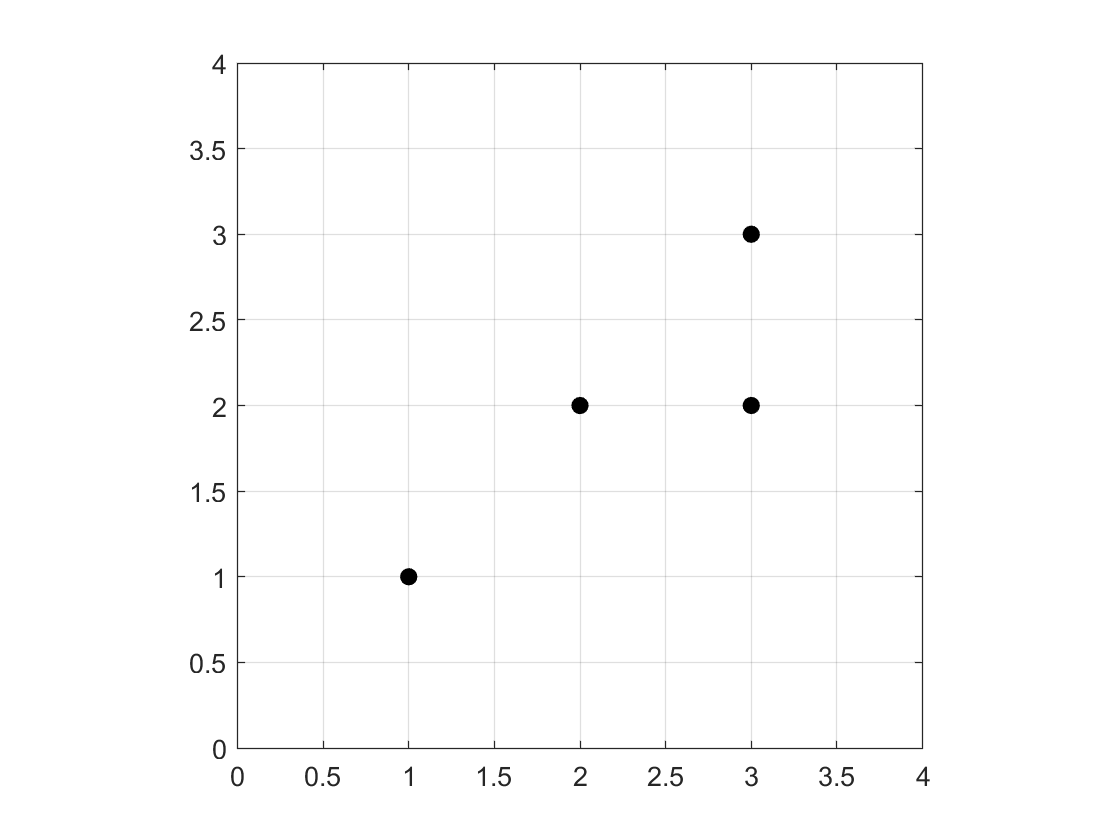

figure;
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)

Set up an equation system -- one per coordinate: 

1., no. of interpolants (per coordinate)

n = length(p(:,1))-1 

n = 3

2., seeking a linear interpolant of type $\mathbf{l}_i(t) = \mathbf{b}_i \cdot t + \mathbf{a}_i$, first, with two unknowns ($\mathbf{a}_i,\,\mathbf{b}_i\in\mathbb{R}^2$) per interpolant, leading to a vector of unknowns: $\left(\,\mathbf{a}_1^\top\,\,\,\mathbf{b}_1^\top\,\,\,\mathbf{a}_2^\top\,\,\,\mathbf{b}_2^\top\,\,\ldots\,\right)^\top$ $-$ per interpolant we get two equations:

- 
$$\mathbf{l}_i(0) = \mathbf{a}_i = \mathbf{p}_i$$


- 
$$\mathbf{l}_i(1) = \mathbf{b}_i + \mathbf{a}_i = \mathbf{p}_{i+1}$$


e = 2 %% number of equations (per interpolant, per coordinate) 

e = 2

Let's set up the equation system:

A = zeros(e*n);    %% empty matrix-setup
B = zeros(e*n, 2); %% empty right-hand side 

Now, for each interpolant, fill in the two equations:

for i = 0:n-1
  % first equation per interpolant 
  A(1+2*i, 1+2*i) = 1; 
  B(1+2*i, :) = p(1+i, :); 
  % second equation per interpolant 
  A(2+2*i, 1+2*i) = 1; 
  A(2+2*i, 2+2*i) = 1; 
  B(2+2*i, :) = p(2+i, :); 
end

Let's look at the left-hand side and right-hand side of the equation system:

A % left-hand side

A =      1     0     0     0     0     0
     1     1     0     0     0     0
     0     0     1     0     0     0
     0     0     1     1     0     0
     0     0     0     0     1     0
     0     0     0     0     1     1


B % RHS 

B =      1     1
     2     2
     2     2
     3     2
     3     2
     3     3


Solve for the unknowns (per coordinate): 

x = A \ B

x =      1     1
     1     1
     2     2
     1     0
     3     2
     0     1


Visualize: 

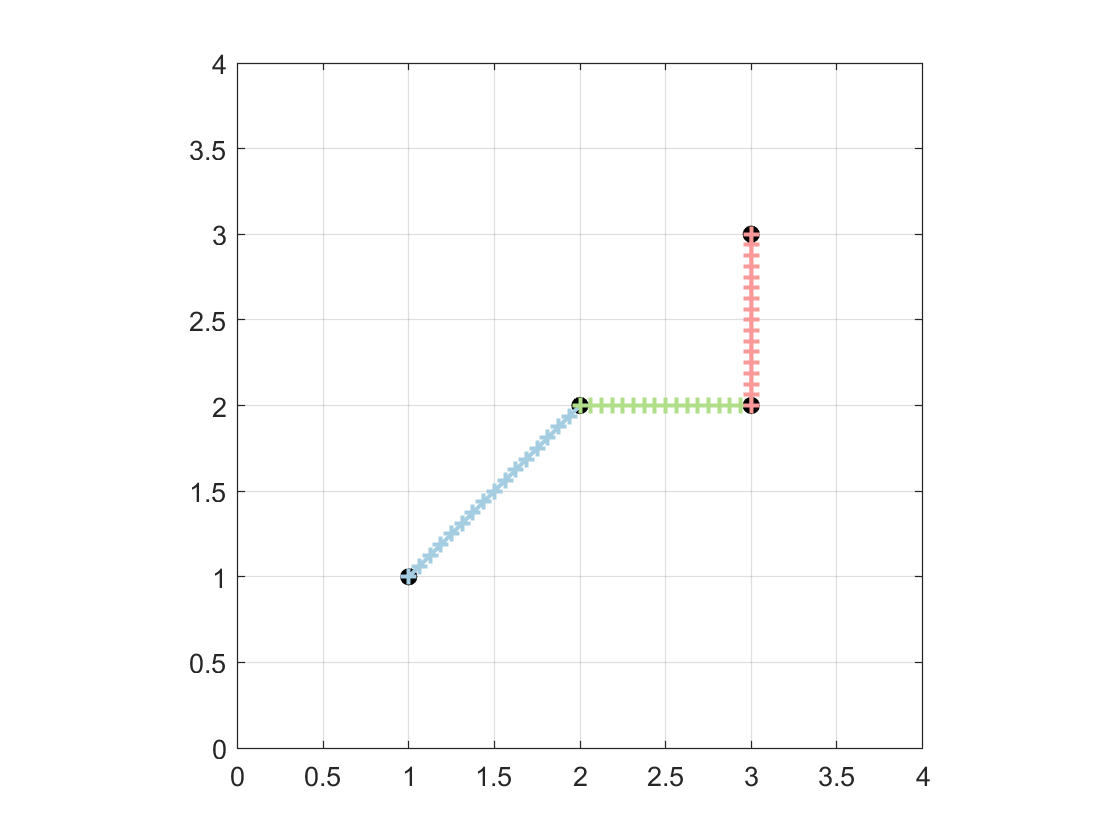

figure; 
cm = [166,206,227; 31,120,180; 178,223,138; 51,160,44; 251,154,153; 227,26,28; 253,191,111; 255,127,0]/256; 
FineLine = linspace(0, 1, 17).'; 
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)
for i = 0:n-1 
  q = x(1+2*i, :) + x(2+2*i, :).*FineLine; 
  plot(q(:,1), q(:,2), '+', 'Color', cm(2*i+1,:), 'LineWidth', 1.5)
  plot(q(:,1), q(:,2),      'Color', cm(2*i+1,:), 'LineWidth', 1.5)
end

3., seeking a quadratic interpolant of type $\mathbf{q}_i(t) = \mathbf{c}_i \cdot t^2 + \mathbf{b}_i \cdot t + \mathbf{a}_i$ with three unknowns ($\mathbf{a}_i, \mathbf{b}_i, \mathbf{c}_i\in\mathbb{R}^2$) per interpolant, leading to a vector of unknowns: $\left(\,\mathbf{a}_1^\top\,\,\mathbf{b}_1^\top\,\,\mathbf{c}_1^\top\,\,\mathbf{a}_2^\top\,\,\mathbf{b}_2^\top\,\,\mathbf{c}_2^\top\,\,\ldots\,\right)^\top  $ $-$ per coordinate we get three equations:

- 
$$\mathbf{q}_i(0)  = \mathbf{a}_i             = \mathbf{p}_{i}$$


- 
$$\mathbf{q}_i(1)  = \mathbf{c}_i + \mathbf{b}_i + \mathbf{a}_i = \mathbf{p}_{i+1}$$


- $\mathbf{t}_i(1) = \mathbf{t}_{i+1}(0)$ with $\mathbf{t}_i(\tau) = \left.\frac{\mathrm{d}\mathbf{q}_i(u)}{\mathrm{d}u}\right|_\tau = 2\,\mathbf{c}_i\cdot\tau + \mathbf{b}_i$  and thus $2\,\mathbf{c}_i+\mathbf{b}_i-\mathbf{b}_{i+1}=0$

e = 3 %% number of equations per interpolant and per coordinate 

e = 3

Setting up the equation system: 

A = zeros(e*n);    %% empty matrix-setup 
B = zeros(e*n, 2); %% empty setup of the right-hand side 

Now filling in the three equations for each interpolant: 

for i = 0:n-1
  % first equation per interpolant 
  A(1+e*i, 1+e*i) = 1; 
  B(1+e*i, :) = p(1+i, :); 
  % second equation per interpolant 
  A(2+e*i, 1+e*i) = 1; 
  A(2+e*i, 2+e*i) = 1; 
  A(2+e*i, 3+e*i) = 1; 
  B(2+e*i, :) = p(2+i, :); 
  % third equation per interpolant and per coordinate
  if i < n-1 
    A(3+e*i, 2+e*i) = 1; 
    A(3+e*i, 3+e*i) = 2; 
    A(3+e*i, 5+e*i) = -1; 
  else
    A(e*n, 2) = 1; 
    B(e*n, :) = [1 1]; %%% default-choice for l_0'(0) (can be chosen)
  end
end

Let's look at the LHS and RHS of this system: 

A

A =      1     0     0     0     0     0     0     0     0
     1     1     1     0     0     0     0     0     0
     0     1     2     0    -1     0     0     0     0
     0     0     0     1     0     0     0     0     0
     0     0     0     1     1     1     0     0     0
     0     0     0     0     1     2     0    -1     0
     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     1     1
     0     1     0     0     0     0     0     0     0


B

B =      1     1
     2     2
     0     0
     2     2
     3     2
     0     0
     3     2
     3     3
     1     1


Solve for the unknowns: 

% choosing some l_0'(0)...
B(3*n, :) = [1.5 0.5] %% or [0.5 1.5] ... %% or [-1 1] ...

B =     1.0000    1.0000
    2.0000    2.0000
         0         0
    2.0000    2.0000
    3.0000    2.0000
         0         0
    3.0000    2.0000
    3.0000    3.0000
    1.5000    0.5000


Now solve:

x = A \ B

x =     1.0000    1.0000
    1.5000    0.5000
   -0.5000    0.5000
    2.0000    2.0000
    0.5000    1.5000
    0.5000   -1.5000
    3.0000    2.0000
    1.5000   -1.5000
   -1.5000    2.5000


Visualize: 

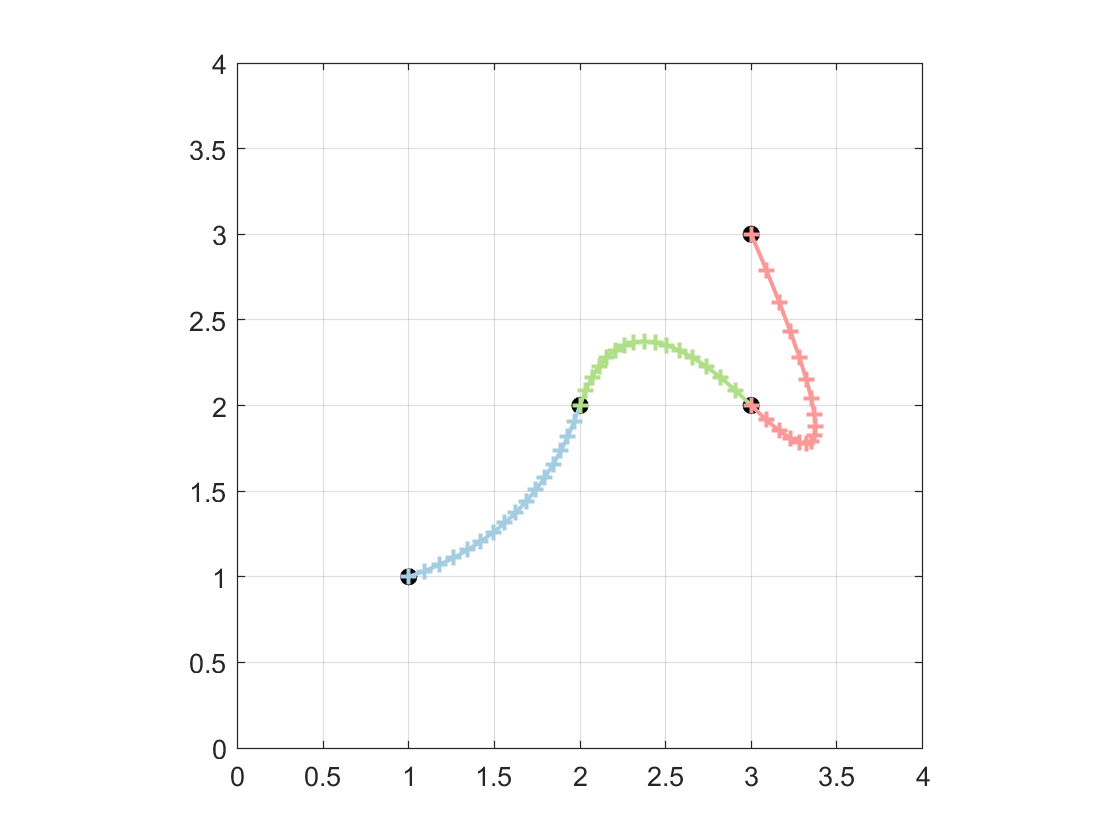

figure; 
FineLine = linspace(0, 1, 17).'; 
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)
for i = 0:n-1 
  q = x(1+3*i, :) + x(2+3*i, :).*FineLine + x(3+3*i, :).*FineLine.*FineLine; 
  plot(q(:,1), q(:,2), '+', 'Color', cm(2*i+1,:), 'LineWidth', 1.5)
  plot(q(:,1), q(:,2),      'Color', cm(2*i+1,:), 'LineWidth', 1.5)
end

Now let's choose something else for the "free equation":  a particular point $\mathbf{r}$ for the middle of the third spline

- since we want $\mathbf{q}_3(\frac{1}{2})=\mathbf{r}$,  

- we get $\mathbf{q}_3(\frac{1}{2}) = \mathbf{c}_3\cdot\frac{1}{4}+\mathbf{b}_3\cdot\frac{1}{2}+\mathbf{a}_3=\mathbf{r}$ as the "free equation"

Entering this into our matrices $\mathbf{A}$ and $\mathbf{B}$, we get:

A(e*n,:) = zeros(1,e*n);        % deleting the last row first
A(e*n,e*n-2:e*n) = [1 1/2 1/4]; % entering the coefficients of the "free equation"
B(e*n,:) = [3.5 2.5];           % choosing a vector r as the RHS of the "free equ."

Next, we solve and visualize:

x = A \ B

x =      1     1
     2     3
    -1    -2
     2     2
     0    -1
     1     1
     3     2
     2     1
    -2     0


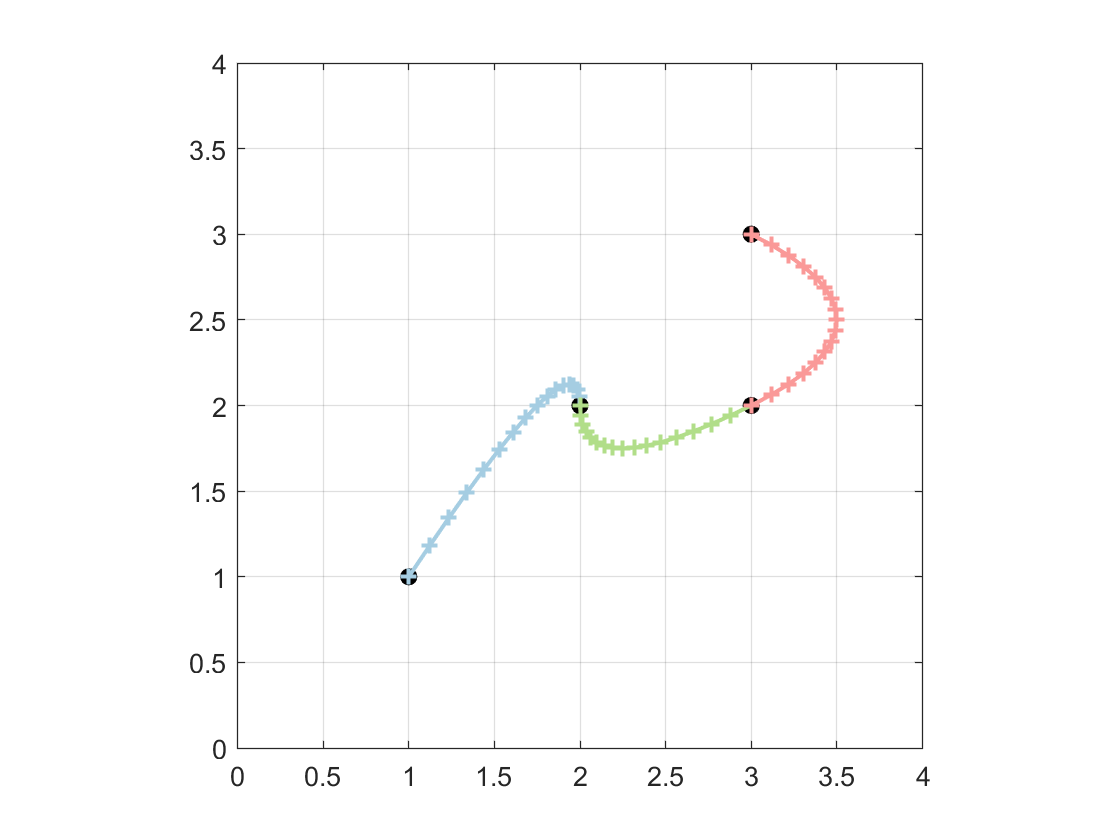

figure; 
FineLine = linspace(0, 1, 17).'; 
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)
for i = 0:n-1 
  q = x(1+3*i, :) + x(2+3*i, :).*FineLine + x(3+3*i, :).*FineLine.*FineLine; 
  plot(q(:,1), q(:,2), '+', 'Color', cm(2*i+1,:), 'LineWidth', 1.5)
  plot(q(:,1), q(:,2),      'Color', cm(2*i+1,:), 'LineWidth', 1.5)
end

By choosing different vectors $\mathbf{r}$, we get several variants of this solution:

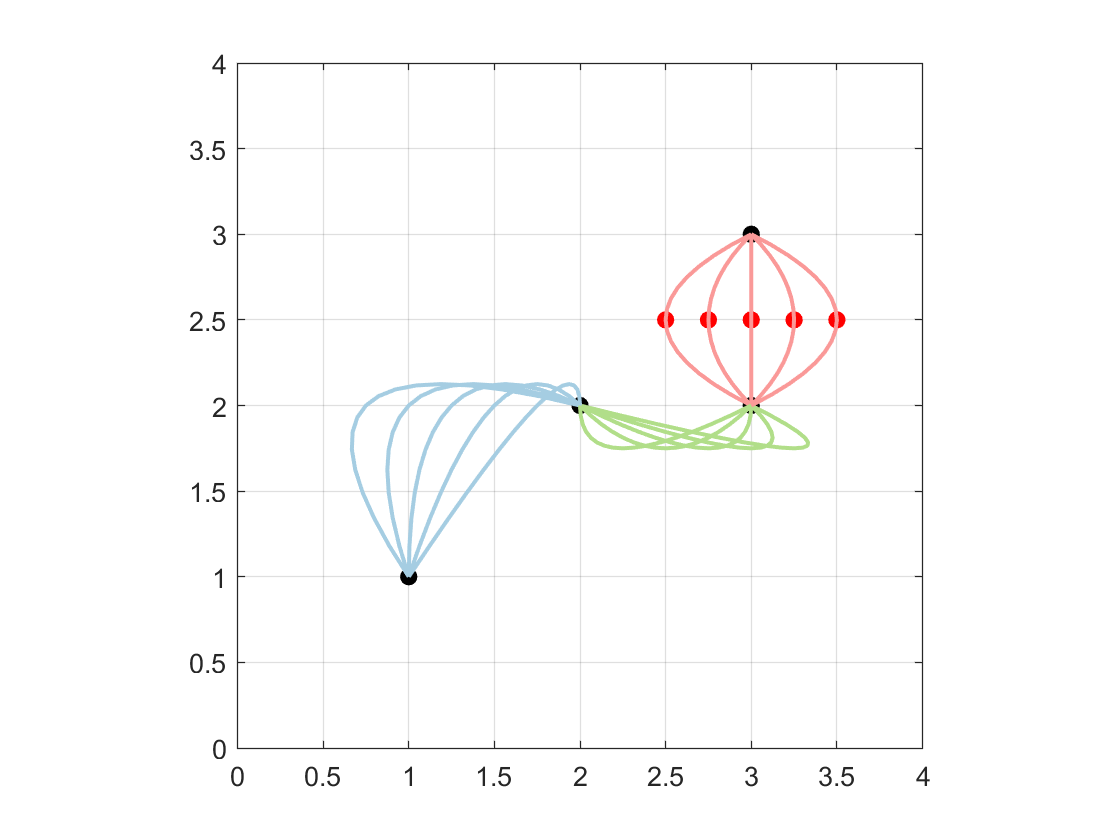

xs = 2.5:0.25:3.5; % let's vary r in its x-coordinate
rs = [xs.' 2.5*ones(length(xs),1)]; % according set of rs
figure; 
FineLine = linspace(0, 1, 17).'; 
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)
for s = 1:length(xs)
    B(e*n,:) = rs(s,:); % set in one of the rs
    plot(rs(s,1), rs(s,2), 'ro', 'MarkerFaceColor', 'r'); % mark the chosen r
    x = A \ B; % solve for the coefficients
    for i = 0:n-1
        q = x(1+3*i, :) + x(2+3*i, :).*FineLine + x(3+3*i, :).*FineLine.*FineLine;
        plot(q(:,1), q(:,2),      'Color', cm(2*i+1,:), 'LineWidth', 1.5)
    end
end

EOF.